# Macro III: Problem Set 1

Deadline: Monday, 20/8/2018

August 2018

Aluno: Bruno Tebaldi de Queiroz Barbosa (C174887)

Professor: Tiago Cavalcanti

Source code disponível em: [https://github.com/btebaldi/Macro3/tree/master/PSet_01](https://github.com/btebaldi/Macro3/tree/master/PSet_01)

## 1. Solving Nonlinear Equations - Bisection Method.

Consider the function:


$$b(x) = e^x - e^{2.2087}$$


Starting from the interval x in [0; 4], find x* such that b(x*) = 0 using the bisection method.

% Limpa variaveis anteriores
clear all
clc

% Define a funcao
b=@(x)(exp(x) - exp(2.2087));

% Determina o zero da funcao via bissection 
x_star=bissection(b,0,4)

x_star = 2.2087

b(x_star)

ans = 1.1287e-08

## Solving Nonlinear Equations - Newton's Method.

%clear variables and console comand
clear all
clc

Consider the function:


$$d(x) = x^{-5} -x^{-3} -c$$


d=@(x,c)(x.^(-5)-x.^(-3)-c);
Dd = @(x,c)(-5*x.^(-6) +3*x.^(-4));

(a) Set c = 1 and plot d on x in [0:6; 10]. Find x* such that d(x*) = 0 using Newton's method.

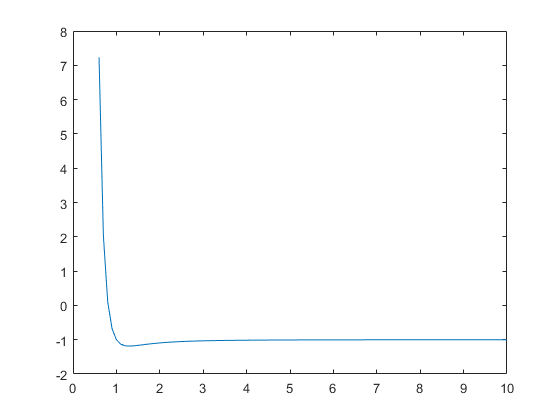

% define o grid
x=0.6:0.1:10;
c=1;

% plot graphics 
plot(x,d(x,c));



x_star = newton(d, Dd, 0.6, c, nan)

x_star = 0.8087

(b) Now construct an equidistant grid for c containing 10 nodes between 1 and 10, and for each value of c on the grid find x*.

% Define o grid
c = 1:1:10;

% inicializa vetor de solucoes
solution = nan(size(c));

% para cada valor no grid realiza metodo de newton
for i = 1:size(c,2)
    solution(i) = newton(d,Dd,0.6, c(i), nan);
end
% imprime vetor de solucoes
solution

solution =     0.8087    0.7419    0.7012    0.6720    0.6495    0.6313    0.6159    0.6028    0.5913    0.5811


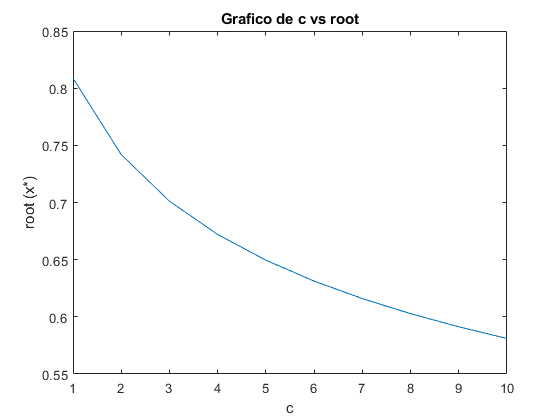

plot(c,solution)
title('Grafico de c vs root');
xlabel('c')
ylabel('root (x*)')

(c) Construct a new equidistant grid for c containing 1000 nodes between 1 and 10, and plot your solution for each value on this grid using a spline.

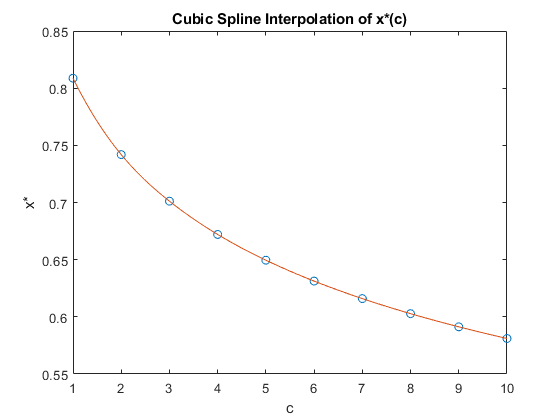

%define o grid
ratio = (10-1)/(1000-1);
spline_points = 1:ratio:10;

% Use the buil-in function to cubic interpolation
spline_func = spline(c,solution); % Linear Interpolation

% Show the picture
plot(c,solution,'o',spline_points,ppval(spline_func,spline_points),'-')
title('Cubic Spline Interpolation of x*(c)');
xlabel('c')
ylabel('x*')

(d) Relabel your solution x* from part (b) x(c). Find the inverse function c(x), and plot it on an equidistant grid of 1000 nodes on x in [0:6; 10] using a spline approximation.

% Setting grid values
UpperBound=10;
LowerBound=0.6;
ratio2 = (UpperBound-LowerBound)/(1000-1);
spline_points2 = LowerBound:ratio2:UpperBound;

% Use the buil-in function to cubic interpolation
spline_func_inverse = spline(solution,c); % Linear Interpolation

% Define c(x) function
C_x = @(x)(ppval(spline_func_inverse,x))

C_x = function_handle with value:
    @(x)(ppval(spline_func_inverse,x))


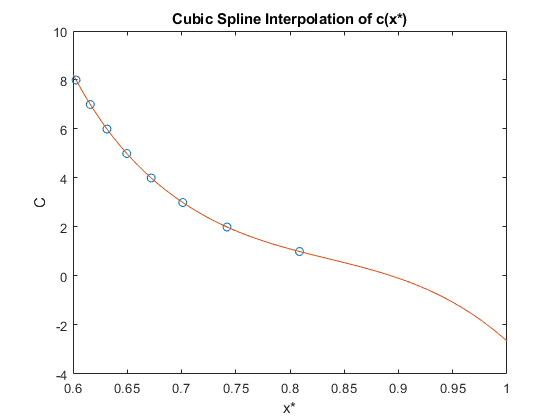


% Show the picture
plot(solution,c,'o',spline_points2,C_x(spline_points2),'-')
title('Cubic Spline Interpolation of c(x*)');
xlabel('x*')
ylabel('C')
xlim([0.6 1]);

(e) Now find the solution to:

0 = c(x) + x:

% define funcao de ponto fixo
fixedPoint = @(x)(C_x(x) + x);

% since the fixedPonit function is continuous in [0.6,10] and 
% fixedPoint(0.6)*fixedPoint(10) < 0 we can use bissection
a= fixedPoint(1);
b= fixedPoint(0.6);

x_fixed = bissection(fixedPoint,a,b)

x_fixed = 0.9448

C_x(x_fixed)

ans = -0.9448

## Approximation Methods: Finite Element Methods.

Consider the function

h(x) on the domain x in [-2; 2]:


$$h(x) = 
\begin{cases}
(x 􀀀-0.5)^2 & \text{if} &0 \le x \le 2\\
(x + 0.5)^2 & \text{if} &-2 \le x \lt 0\end{cases}
$$


Approximate h(x) with a cubic spline, using n = 5 equally spaced nodes. Plot the function along with your approximation and calculate the root mean squared error of your approximation over the fine grid, with interval 0.0001.

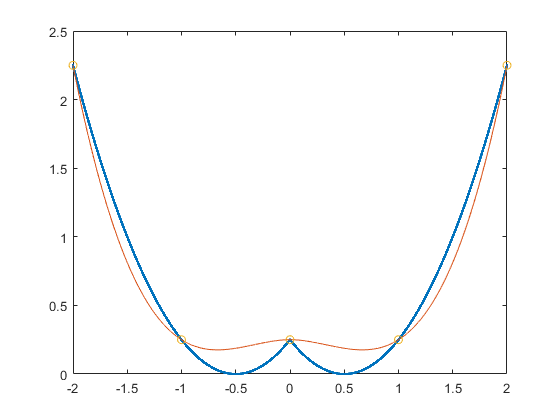

% limpa variaveis anteriores
clear all
clc

% Define os nodes
ratio = (2 - (-2))/(5-1);
nodes_5=-2:ratio:2;

% define os grid points
gridPoints = -2:0.0001:2;

% Use the buil-in function to cubic interpolation
spline_func_5 = spline(nodes_5,h(nodes_5)); % Linear Interpolation

% plotagem dos graficos e da spline function
plot(gridPoints, h(gridPoints), '.', ...
    gridPoints, ppval(spline_func_5,gridPoints), '-', nodes_5,h(nodes_5), 'o');


% Calcula o RMSE
rmse_5 = RMSE(h(gridPoints), ppval(spline_func_5,gridPoints));
fprintf('RMSE=%f\n', rmse_5);

RMSE=0.138011


(b) Approximate h(x) with a cubic spline, using n = 10 equally spaced nodes. Plot this new approximation along with both the actual function and your approximation from (a) and calculate the root mean squared error of your approximation over the fine grid, with interval 0.0001. Explain the reasons for the differences in your answers.

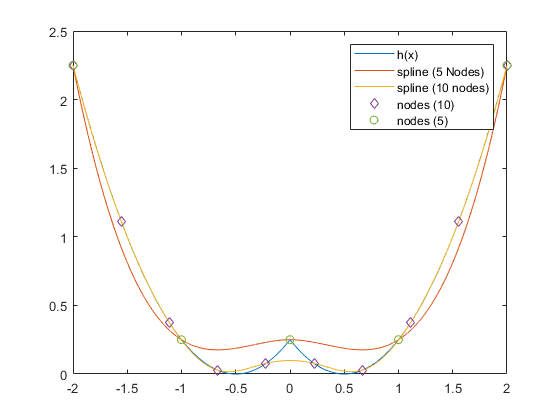


% Define os nodes
ratio = (2 - (-2))/(10-1);
nodes_10=-2:ratio:2;

% Use the buil-in function to cubic interpolation
spline_func_10 = spline(nodes_10,h(nodes_10)); % Linear Interpolation

% plotagem dos graficos e da spline function
plot(gridPoints,h(gridPoints),'-',...
    gridPoints,ppval(spline_func_5,gridPoints),'-', ...
    gridPoints,ppval(spline_func_10,gridPoints), '-',...
    nodes_10, h(nodes_10), 'd', nodes_5, h(nodes_5),'o')
legend({'h(x)','spline (5 Nodes)','spline (10 nodes)','nodes (10)', 'nodes (5)'})

% Calcula o RMSE
rmse_10 = RMSE(h(gridPoints), ppval(spline_func_10,gridPoints));
fprintf('RMSE (10 nodes)=%f\tRMSE (5 nodes)=%f\n', rmse_10, rmse_5);

RMSE (10 nodes)=0.027642	RMSE (5 nodes)=0.138011


A diferença no RMSE é devido a quantidade de nós, quanto maior a quantidade de nós mais precissa sera a C-Spline que será construida.

## Growth Model

Consider the following growth model with taxes.

**Households.** There is a continuum of identical households with measure one. Each household has $N_t$ members, which grows at rate $\eta$. The representative household owns the initial capital stock, $K_0$, and each household member has a unit of productive time in each period. Let $h_t$ and $l_t$ be hours worked and leisure by each household member, respectively, such that $h_t+l_t = 1$. Preferences of the representative household is given by the following utility function:


$$U = \sum_{t=0}^\infty \beta^t N_t [ln(c_t) + \theta ln(l_t)]$$


The evolution of capital stock is:


$$K_{t+1} = (1-\delta)K_t+x_t \text{, where } \delta \in (0,1)$$


where $x_t$ is investment at t.

(Important: Note the difference between the household and a household member - You can think about this as a dynasty such that there is perfect altruism towards future generations)

**Production Sector**. There is a continuum of measure one of identical firms. Let At be a productivity factor which evolves according to $A_{t+1}=(1+\gamma)A_t$. Let $K_t$ be the capital stock, and $H_t$ be the total hours employed in the production of good $Y_t$ by the representative firm. The technology is given by


$$Y_t = K^{\alpha}_t (A_tH_t)^{1-\alpha}$$


The representative firm rents capital and labor from households.

**Government Sector**. There is a government which finances $G_t$ expenditures through taxes on consumption, $\tau^c$, labor income, $\tau^h$, and capital income, $\tau^k$. Suppose that in every period the government balances its budget, such that


$$G_t = \tau^c N_t c_t + \tau^h w_t N_t h_t + \tau^k r_t k_t$$


(Comment: Think about a continuous measure one of households. This implies that each household is very tiny. Since they are identical, this implies that you can solve the problem of a household who represents the others. Finally, the average of the economy is similar to the aggregate)

(a) Define a competitive equilibrium for this economy and write down the equations that describe the equilibrium of the system.

(This is the most important part of the problem. You can look at your macro text book)

Seja

 
$$h_t +l_t =1 \\
N_{t+1} = (1+\eta)N_t \\
A_{t+1} = (1+\gamma)A_t
$$


**problema das *****Households***

A utilidade de uma *household* é dado por:


$$U=\sum_{t=0}^{\infty}{\beta^t N_t [ ln(c_t) + \theta ln(l_t)]}$$


Vamos definir o investimento por trabalhador e capital por trabalhador como 


$$k_t = K_t/N_t \\
i_t = x_t/N_t$$


A restrição orçamentaria da husehold é que as receitas devem ser iguais as despesas. logo temos despesas: Consumo e investimento; Receitas: lucro do aluguel do capital e salario do trabalho. Sendo assim a restrição orçamentária fica:


$$N_tC_t +x_t = r(t)K_t + N_t w(t)h_t \\
N_tC_t +N_ti_t = r(t)N_tk_t + N_t w(t)h_t$$


Como temos a presenca de impostos ficamos com a seguinte equação

$C_t(1+\tau^c) +i_t = R(t)(1-\tau^k)k_t + w(t) (1-\tau^h)h_t$   (eq:1)

Montano o lagrangeano temos:


$$\mathcal{L} = \sum_{t=0}^{\infty}{\beta^t N_t [ ln(c_t) + \theta ln(1-h_t)]} - \sum_{t=0}^{\infty}{\beta^t \lambda_t [ C_t(1+\tau^c) +i_t - r(t)(1-\tau^k)k_t - w(t) (1-\tau^h)h_t]}$$


$\frac{\partial\mathcal{L}}{\partial c_t}=0 \Rightarrow \frac{1}{c_t}=\lambda_t\frac{(1+\tau^c)}{N_t}$   (eq:2)

$\frac{\partial\mathcal{L}}{\partial c_t}=0 \Rightarrow \frac{\theta}{1-h_t} = \frac{\lambda_t}{N_t}$   (eq:3)

pelo teorema do envelope temos

$\frac{\partial\mathcal{L}}{\partial k_{t+1}}=0 \Rightarrow \lambda_t = \beta \lambda_{t+1} \frac{1-\delta +r(t+1)(1-\tau^k)}{(1+\eta)$   (eq:4)

substituindo das equacoes (4) (3) e (2) temos:

$\frac{c_{t+1}}{c_t}=\beta(1-\delta +r(t+1)(1-\tau^k))$   (eq:5)

$\frac{\theta c_t}{1-h_t}=w(t) \frac{(1-\tau^h)}{(1+\tau^c)}$    (eq:6)

**Problema das frimas**

As firmas sempre maximizam lucro para qualquer t, logo temos:

$Y_t=K_t^\alpha(A_tH_t)^{1-\alpha}$  (eq:7)


$$max_{H_t,K_t}\{Y_t - W(t)H_t -R(t)K_t\}$$


O que leva as seguintes condições:

$R(t) = \alpha\left(\frac{A_tH_t}{K_t}\right)^{1-\alpha}$ (eq:8)

$W(t) = (1-\alpha)A_t^{1-\alpha}\left(\frac{K_t}{H_t}\right)^{\alpha}$  (eq:9)

**Market Clear**

No equilibrio os mercados tem de se igualar, logo


$$w(t) = W(t) \\
r(t) = R(t) \\
N_th_t = H_t$$
 

Para o governo temos:


$$G_t = \tau^cc_tN_t + \tau^hN_tw(t)h_t+\tau^kr(t)K_t$$



$$G_t = \tau^cc_tN_t + \tau^hN_tw(t)h_t+\tau^kr(t)N_tk_t$$


$g_t = \tau^cc_t + \tau^hw(t)h_t+\tau^kr(t)k_t$  (eq:10)

Da restricao de recursos da economia podemos definir a produção per capita (y) 

$y_t=Y_t/N_t \\
y_t =c_t + i_t +g_t$ (eq:11)

**Evolucao do capital**

A equacao de evolução do capital é dada como:


$$K_{t+1} = (1-\delta)K_{t} + x_t$$


Definindo em termos de trabalhador efetivo ($A_tN_t$) temos:

$\frac{K_{t+1}}{A_tN_t} = (1-\delta)\frac{K_t}{A_tN_t} + \frac{x_t}{A_tN_t}$ (eq:12)

Vamos definir as variaveis em termos de trabalhador efetivo. logo temos:


$$\tilde{i}_t = \frac{i_t}{A_t} = \frac{x_t}{A_t N_t}$$



$$\tilde{y}_t = \frac{y_t}{A_t} = \frac{Y_t}{A_t N_t}$$
 


$$\tilde{k}_t = \frac{k_t}{A_t} = \frac{K_t}{A_t N_t}$$
 


$$\tilde{g}_t = \frac{g_t}{A_t} = \frac{G_t}{A_t N_t}$$
 

Sendo assim a equação (12) fica

$(1+\eta)(1+\gamma)\tilde{k}_{t+1} = (1-\delta)\tilde{k}_{t} + \tilde{i}_t$ (eq: 13)

Note que nas equações (8) e (9) temos

$R(t) = \alpha\left(\frac{h_t}{\tilde{k}_t}\right)^{1-\alpha}$ (eq:15)

$\frac{W(t)}{A_t} = (1-\alpha)\left(\frac{\tilde{k}_t}{h_t}\right)^{\alpha}$ (eq:16)

Sendo assim temos, das equacoes (5) (6) (7) (8) (9) (10) (11) (13):

$\frac{c_{t+1}}{c_t}=\frac{\beta}{(1+\gamma)}\left[1-\delta +\alpha \left(\frac{h_{t+1}}{\tilde{k}_{t+1}}\right)^{1-\alpha}(1-\tau^k)\right]$   (eq:17)

$\frac{\theta \tilde{c}_t}{1-h_t}=(1-\alpha)\left(\frac{\tilde{k}_t}{h_t}\right)^\alpha \frac{(1-\tau^h)}{(1+\tau^c)}$    (eq:18)

$(1+\eta)(1+\gamma)\tilde{k}_{t+1} = (1-\delta)\tilde{k}_{t} - (1+\tau^c)\tilde{c}_t +\tilde{k}_t^\alpha h_t^{1-\alpha}\left[1-\tau^h(1-\alpha)-\tau^k\alpha\right]$ (eq:19)

As equacoes (17), (18) e (19) são as equações que descrevem o equilíbrio do sistema.

(b) What are the variables growth rate along the balanced growth path equilibrium? (hint: Assume that taxes are constant and that G grows at the same rate of Y such that the "government size", G/Y , is also constant.)

Vamos designar $g_i$ como sendo a taxa de crescimento da variável i, onde para a variável c temos:


$$g_c = \frac{c_{t+1}}{c_t}$$


No *balanced grow path* temos que $g_i$ é contante, sendo assim:


$$g_c = \frac{c_{t+1}}{c_t} = \frac{c_{t+2}}{c_{t+1}}$$


da equacao (17) temos:


$$\frac{ \frac{c_{t+1}}{c_t} }{ \frac{c_{t+2}}{c_{t+1}} }= 1 = \frac{ \frac{\beta}{(1+\gamma)}\left[1-\delta +\alpha \left(\frac{h_{t+1}}{\tilde{k}_{t+1}}\right)^{1-\alpha}(1-\tau^k)\right] }{ \frac{\beta}{(1+\gamma)}\left[1-\delta +\alpha \left(\frac{h_{t+2}}{\tilde{k}_{t+2}}\right)^{1-\alpha}(1-\tau^k)\right] } \Rightarrow \left(\frac{h_{t+2}}{\tilde{k}_{t+2}}\right)^{1-\alpha} = \left(\frac{h_{t+1}}{\tilde{k}_{t+1}}\right)^{1-\alpha}$$



$$\left(\frac{h_{t+2}}{\tilde{k}_{t+2}}\right)^{1-\alpha}=\left(\frac{h_{t+1}}{\tilde{k}_{t+1}}\right)^{1-\alpha} \Rightarrow \frac{K_{t+1}}{K_t}=(1+\gamma)(1+\eta)\frac{h_{t+1}}{h_t}$$
 

$g_K=(1+\gamma)(1+\eta)g_h$  (eq:20)

Note que $g_h=1$ e consequentemente $g_l=1$. Não é possigem ter $g_h\neq1$por causa das condições de Inada. Se $g_h\neq1$ a utilidade marginal do lazer seria infinita (caso >1) ou a produção seria zero (caso <0).

logo

$g_h=g_l=1$    (eq:21)


$$g_Y = \frac{Y_{t+1}}{Y_t} = g_k^\alpha(1+\gamma)^{1-\alpha}(1+\eta)^{1-\alpha}g_h^{1-\alpha}$$


$g_Y = (1+\gamma)(1+\eta)$ (eq:22)

por hipotese temos

$g_G=g_Y$ (eq:23)

Da equação (18) temos:


$$\frac{\frac{\theta \tilde{c}_{t+1}}{1-h_{t+1}}}{\frac{\theta \tilde{c}_t}{1-h_t}}=\frac{(1-\alpha)\left(\frac{\tilde{k}_{t+1}}{h_{t+1}}\right)^\alpha \frac{(1-\tau^h)}{(1+\tau^c)}}{(1-\alpha)\left(\frac{\tilde{k}_t}{h_t}\right)^\alpha \frac{(1-\tau^h)}{(1+\tau^c)}} \Rightarrow g_c=(1+\gamma)^{1-\alpha} (g_K)^\alpha(1+\eta)^{-\alpha}(g_h)^{-\alpha}$$


$g_c=(1+\gamma)$ (eq: 24)

As equações (24)(22)(21)(20) são as variáveis no balanced grow path

(c) Write down the equivalent stationary system. (You have to transform your variable such that they are stationary in the long-run)

Da equação 17 temos:


$$\frac{c}{c}=\frac{\beta}{(1+\gamma)}\left[1-\delta +\alpha \left(\frac{h}{\tilde{k}}\right)^{1-\alpha}(1-\tau^k)\right] =1$$



$$(1+\gamma)=\beta(1-\delta)+\alpha\beta\frac{h^{1-\alpha}}{\tilde{k}^{1-\alpha}}(1-\tau^K)$$



$$\tilde{k} =\left[\frac{\alpha\beta(1-\tau^K)}{(1+\gamma)-\beta(1-\delta)}\right]^{\frac{1}{1-\alpha}}h$$



$$X :=\left[\frac{\alpha\beta(1-\tau^K)}{(1+\gamma)-\beta(1-\delta)}\right]^{\frac{1}{1-\alpha}}$$


$\tilde{k} =X h$   (eq:25)

Da equação (18) temos


$$\frac{\theta \tilde{c}}{1-h}=(1-\alpha)\left(\frac{\tilde{k}}{h}\right)^\alpha \frac{(1-\tau^h)}{(1+\tau^c)} = (1-\alpha)\left(\frac{Xh}{h}\right)^\alpha \frac{(1-\tau^h)}{(1+\tau^c)} = (1-\alpha)X^\alpha \frac{(1-\tau^h)}{(1+\tau^c)}$$



$$Z:=(1-\alpha)X^\alpha\frac{(1-\tau^h)}{(1+\tau^c)}$$


$\tilde{c} = \frac{(1-h)}{\theta}Z$   (eq:26)

da equação (19) temos


$$(1+\eta)(1+\gamma)\tilde{k} = (1-\delta)\tilde{k} - (1+\tau^c)\tilde{c} +\tilde{k}^\alpha h^{1-\alpha}\left[1-\tau^h(1-\alpha)-\tau^k\alpha\right]$$



$$(1+\eta)(1+\gamma)Xh = (1-\delta)Xh - (1+\tau^c)\frac{(1-h)}{\theta}Z +Xh^\alpha h^{1-\alpha}\left[1-\tau^h(1-\alpha)-\tau^k\alpha\right]$$



$$[(1+\eta)(1+\gamma)-(1-\delta)]Xh = hX^\alpha[1-\tau^h(1-\alpha)-\tau^k\alpha]- (1+\tau^c)\frac{(1-h)Z}{\theta}$$



$$D:= [(1+\eta)(1+\gamma)-(1-\delta)]X\\
E:=X^\alpha[1-\tau^h(1-\alpha)-\tau^k\alpha]$$



$$Dh = hE- (1+\tau^c)\frac{(1-h)Z}{\theta}$$



$$(D-E)h -\frac{(1+\tau^c)Z}{\theta}h=- \frac{(1+\tau^c)Z}{\theta}$$



$$F:=\left[(D-E)-\frac{(1+\tau^c)Z}{\theta}\right]$$


$h=-\frac{(1+\tau^c)Z}{\theta F}$  (eq:27)

As equações (25), (26) e (27) são as equaçoes que definem os valores de equilibrio do sistema.

(d) Now suppose that $\beta = 0.98$,$\delta=0.08$, $\gamma=0.015$, $\alpha=0.4$, $\theta = 2$, $\tau^c=0.15$,$\tau^h=0.25$,$\tau^k=0.15$. Write down a program that solves the transitional dynamics of the equilibrium system by using one of the methods of solving a system of nonlinear equations (e.g., Newton, Secant or fsolve). Assume that $K_0 = 0.8 K_{SS}$

%% Limpeza de variaveis
clear all
clc
%% Setup Inicial
%parametros do sistema
beta=0.98;
delta=0.08;
gamma=0.015;
alpha=0.4;
theta=2;
eta=0.02;
%parametros do governo
tau_c=0.15;
tau_h=0.25;
tau_k=0.15;

% numero de periodos analisados (grid)
T=100;      

param_sys = [beta,delta,gamma,alpha,theta,eta];
param_gov = [tau_c,tau_h,tau_k];

% definicao de funcao salario e funcao juros
w_t=@(h,k)((1-alpha)*(k/h)^alpha);
r_t=@(h,k)(alpha*(h/k)^(1-alpha));

% calculo do steady state
[h_ss,c_ss,k_ss,g_ss,y_ss,i_ss]=CalculoSteadyState(param_sys, param_gov, w_t, r_t);

% definicao do ponto inicial
h_0 = 0.8*h_ss;
c_0 = 0.8*c_ss;
k_0 = 0.8*k_ss;
g_0 = 0.8*g_ss;

% defino o vetor de variaveis iniciais e finais
initial_state=[k_0, h_0];
final_state = [k_ss, h_ss];

% calculo a trajetoria de equilibrio
[k,h] = CalculaTrajetoriaEquilibrio(initial_state, final_state, T, param_sys, ...
    param_gov);


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0         203        0.328884            0.19         0.01
     1         406      0.00408258          0.0151        0.001       0.365058
     2         609     0.000699417        0.000632       0.0001       0.883611
     3         812     1.12282e-05         0.00016        1e-05       0.762828
     4        1015     3.45496e-09        3.23e-06        1e-06        0.11424
     5        1218     3.77961e-14        1.07e-09        1e-07     0.00205133
     6        1421     3.15873e-14        6.04e-14        1e-08    2.80518e-06

Equation solved. The sum of squared function values, r = 3.158729e-14, is less
than sqrt(options.FunctionTolerance) = 1.000000e-03. The relative norm of the gradient of
r, 3.177734e-


% Calculo y, c, g e i
[y,c,g,i] = Calculo_YCGI(k,h, param_sys, param_gov);



(e) Plot the dynamics of capita, consumption, investment, labor and output per capita.

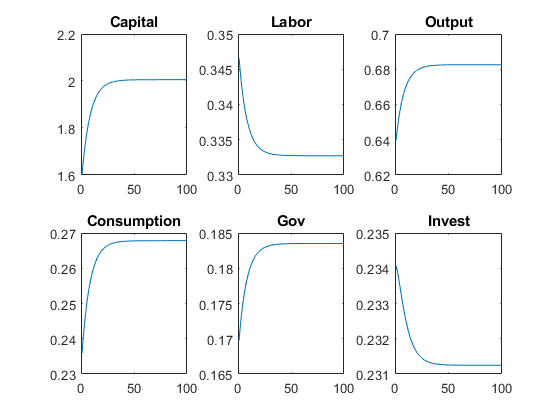

% imprime os graficos
Data=[k,h,y,c,g,i];
Legenda={'Capital', 'Labor', 'Output', 'Consumption', 'Gov', 'Invest'};
PlotStuff(Data, Legenda, 100);

(f) Now let's study the following tax reform: Suppose that the government reduces the tax on capital income from 0.15 to 0.10 and the government increases the tax on labor income in order to finance the same level of spending (i.e. in the long run the tax reform is revenue neutral). Write a program to implement this tax reform. Assume that prior the reform the initial capital stock is in the steady-state. Show the dynamics and analyze this reform. Use economic arguments to interpret your results.

Se temos que o gasto do governo fica constante no longo prazo então temos que 


$$g_{SS\_OLD} = g_{SS\_NEW}$$


Logo temos uma função que tem como argumento o $\tau^h$, que indica a variacao do *Steady State* antigo para o *Steady State.*


$$VariacaoGss(\tau^h) = g_{SS}(\tau^h)-g_{SS\_Old}=0$$


% New tau
tau_k_new = 0.1;

% defino um chute inicial para o novo valor de tau_h
tau_h_new = 0.5;

% Definindo opcoes de otimizacao
options=optimoptions('fsolve','Display','iter');

% otimiza tau_h_new, a funcao de variacao do gasto do governo de maneira que a
% variacao seja zero.
tau_h_new=fsolve(@(tau_h_new)VariacaoGss(tau_h_new, tau_k_new, param_sys, ...
    param_gov, w_t, r_t, g_ss),tau_h_new ,options);


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          2      0.00725209                        0.0313               1
     1          4     3.58951e-08       0.231387          7e-05               1
     2          6     1.89707e-19    0.000512861       1.61e-10               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<


% cria o vetor de novos parametros do governo
param_gov_new =[tau_c,tau_h_new,tau_k_new];

% calculo novo steady state
[h_ss_new,c_ss_new,k_ss_new,g_ss_new,y_ss_new,i_ss_new] =  ...
    CalculoSteadyState(param_sys, param_gov_new, w_t, r_t);

% Definido parametros de condicoes iniciais e finais
% neste caso nosso ponto de saida eh o steady state anterior e o final sera
% o novo steady state calculado
initial_state=[k_ss, h_ss];
final_state = [k_ss_new, h_ss_new];

% calculo a trajetoria de equilibrio
[k_new,h_new] = CalculaTrajetoriaEquilibrio(initial_state, final_state, T, ...
    param_sys, param_gov_new);


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0         203      0.00510428          0.0221         0.01
     1         406     0.000607099         0.00021        0.001      0.0917595
     2         609     0.000180341        7.86e-05       0.0001       0.380149
     3         812     3.47013e-06        4.58e-05        1e-05       0.437012
     4        1015     1.16528e-09        1.11e-06        1e-06      0.0719121
     5        1218     1.07979e-14         3.9e-10        1e-07     0.00135056
     6        1421     7.67328e-15        4.17e-14        1e-08    2.23482e-06

Equation solved. The sum of squared function values, r = 7.673284e-15, is less
than sqrt(options.FunctionTolerance) = 1.000000e-03. The relative norm of the gradient of
r, 1.885632e-

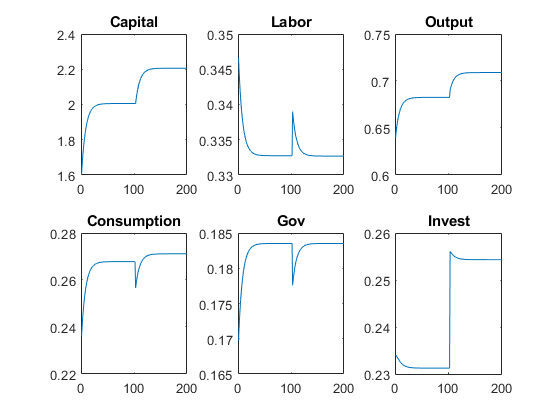


% Calculo y, c, g e i
[y_new, c_new, g_new, i_new] = Calculo_YCGI(k_new, h_new, param_sys, param_gov_new);

% monto a sequancia antiga de equilibrio junto com a nova
k_total = [k;k_new];
h_total = [h;h_new];
y_total = [y;y_new];
c_total = [c;c_new];
g_total = [g;g_new];
i_total = [i;i_new];

% imprime os graficos
Data=[k_total, h_total, y_total, c_total, g_total, i_total];
Legenda={'Capital', 'Labor', 'Output', 'Consumption', 'Gov', 'Invest'};
PlotStuff(Data, Legenda, 200);

(g) Calculate the long run welfare implications of this tax reform in terms of consumption:


$$[ln((1+w)c^{new}) +\gamma ln(l^{new})]-[ln(c^{old})+ \gamma ln(l^{old})]$$


$w$ is the percentage of consumption that the household must be compensated (or pay) to accept this tax reform. How about the transitional dynamics? (Related to this exercise see Cavalcanti (2008). "Tributos sobre a Folha ou sobre o Faturamento? Efeitos Quantitativos Para o Brasil" RBE.)

f=@(omega)(log((1+omega)*c_ss_new)+gamma*log(1-h_ss_new))- ...
    (log(c_ss)+gamma*log(1-h_ss));
omega=fsolve(f,0.5);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



fprintf('omega = %f',omega);

omega = -0.012276

## Question 5

Write down a code by using one of the methods of solving a system of nonlinear equations (e.g., Newton, Secant or fsolve) to reproduce Figure 1 of Gourinchas and Jeanne (2006, Review of Economic Studies), "The Elusive Gains from International Financial Integration."

Na economia fechada as equações que descrevem a economia é:


$$\frac{c_{t+1}}{c_t}=\beta (1-\delta +r_{t+1}) \\
N_tc_t +K_{t+1} = [1- \delta +r_t]K_t + w_tN_t \\
w_t = K_t^\alpha(1-\alpha)(A_tN_t)^{-\alpha}A_t \\
r_t = \alpha K_t^{\alpha-1}(A_tN_t)^{1-\alpha}$$


Desenvolvendo temos a equação de equilibrio


$$\frac{-gn\tilde{k}_{t+2}+[1-\delta+\alpha\tilde{k}_{t+1}^{\alpha-1}]\tilde{k}_{t+1}+(1-\alpha)\tilde{k}_{t+1}^\alpha}{-gn\tilde{k}_{t+1}+[1-\delta+\alpha\tilde{k}_{t}^{\alpha-1}]\tilde{k}_{t}+(1-\alpha)\tilde{k}_{t}^\alpha}=\frac{\beta}{g} (1-\delta +\alpha\tilde{k}^{\alpha-1}_{t+1})$$


As variações do welfare são calculadas por sua vez pela equação:


$$\Delta = U_{open}-U_{closed} = \sum_{t=0}^{\infty}{\beta^tN_tln(c_t^o)} - \sum_{t=0}^{\infty}{\beta^tN_tln(c_t^c)}$$



$$\Delta = \sum_{t=0}^{\infty}{\beta^tN_tln\left(c_t^o\right)} - \sum_{t=0}^{\infty}{\beta^tN_tln\left(c_t^c\right)} = \frac{N_0ln\left(\tilde{c}^o_0\right)}{1-\beta\eta} -N_0 \sum_{t=0}^{\infty}{\beta^t\eta^tln\left(\tilde{c}^c_t\right)}$$


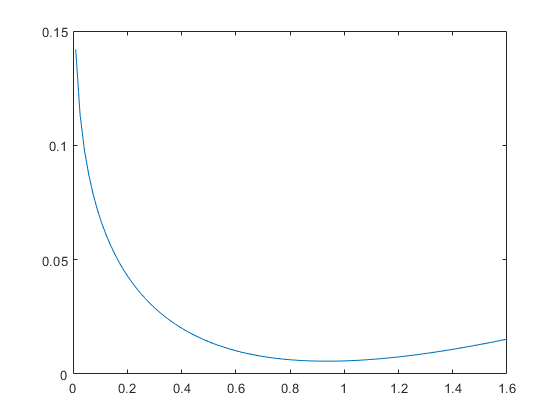

clear all
clc
%Variaveis Iniciais
A = 1;
n0 = 1;
alpha = 0.3;
delta = 0.06;
ga = 1.012;
gn = 1.0074;
beta = 0.96;
gamma = 1;
open = 0;
T=100;

% Calcula steady state 
k_ss = (alpha/((ga/beta) + delta - 1))^(1/(1-alpha));
r_star = (ga^gamma)/(beta);


% Inicializa o grid de analise
grid_spaces = linspace(0.01, 1.6, 100);

% Inicializa o vetor de resltado
mu = nan(size(grid_spaces));

% Para cada ponto do grid realiza a conta de waelfare
for ncount=1:numel(grid_spaces)
    
    % seleciona ponto do grid
    grid = grid_spaces(ncount);
    
    % define o ponto inicial como um fator do ponto do grid
    k_0 = grid*k_ss;
    
    % Definicao da trajetoria de chute inicial
    k_guess = linspace(k_0, k_ss, 102);
    k_guess = k_guess(2:end-1);
    
    % Definido parametros de condicoes iniciais e finais e parametros do gov
    param_conditions=[k_0, k_ss];
    param_economy = [A, n0, alpha, delta, ga, gn, beta, gamma, open];
    
    % resolve o modelo dado a economia
    k_optimal = solve_path(k_guess, param_economy, param_conditions);
    
    % adiciono os pontos iniciais e finais ao vetor para o calculo do consumo
    k_optimal = [k_0, k_optimal, k_ss, k_ss];
    
    % calcula consumo relacionado ao k otimo
    c_optimal  = nan(1,numel(k_optimal)-1);
    for i=1:numel(k_optimal)-1
        c_optimal(i)  = consumption(k_optimal(i),k_optimal(i+1),param_economy);
    end
    
    % calcula wellfare
    welf_aut = Welfare(c_optimal, param_economy, param_conditions);
    
    % Troco sistema para economia aberta
    param_economy = [A, n0, alpha, delta, ga, gn, beta, gamma, 1];
    
    % resolve o modelo dado para a economia aberta
    k_optimal = solve_path(k_guess, param_economy, param_conditions);
    
    % adiciono os pontos iniciais e finais ao vetor para o calculo do consumo
    k_optimal = [k_0, k_optimal, k_ss, k_ss];

    % calcula consumo relacionado ao k otimo
    c_optimal  = nan(1,numel(k_optimal)-1);
    for i=1:numel(k_optimal)-1
        c_optimal(i)  = consumption(k_optimal(i),k_optimal(i+1),param_economy);
    end
    
    % calcula wellfare
    welf_int = Welfare(c_optimal, param_economy, param_conditions);
    
    % calcula funcao mu conforme formula do artigo
    mu(ncount)= exp((1-gn*beta)*(welf_int - welf_aut))-1; 
end

% Inicia novo grafico de figura e plota a figura
figure
plot(grid_spaces, mu)